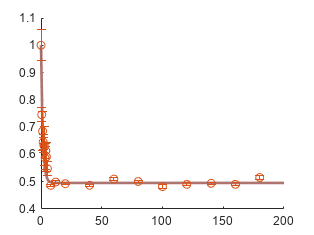

clear all
close all
colors=npg(100);

% Coherent state Ramsey fringes

main_dir='E:\Data\2022-12-10\Abs-4329';

f_pop_decay_coherent=openfig([main_dir,'\PopulationDecay.fig']);

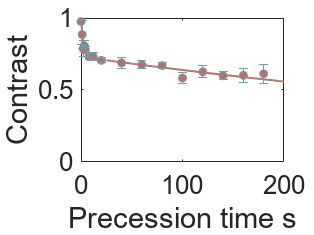

f_amp_decay_coherent=openfig([main_dir,'\AmpDecay.fig']);

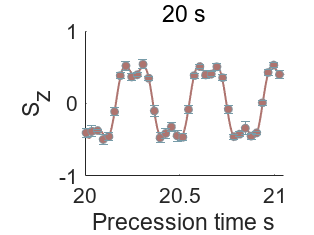


f_Ramsey_coherent_1=openfig([main_dir,'\Figure_8.fig']);

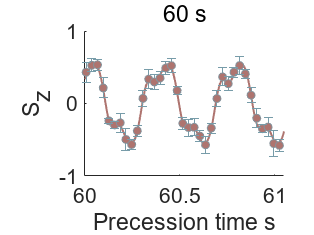

f_Ramsey_coherent_2=openfig([main_dir,'\Figure_10.fig']);

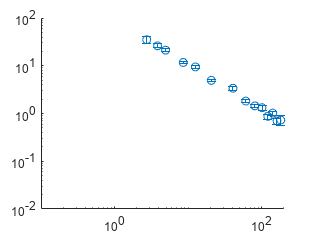


f_sensitivity_coherent=openfig([main_dir,'\SensitivityDecay.fig']);


% Cat state Ramsey fringes
main_dir='\\Artemis-pc\e\Data\2022-12-24\Abs-3551';

f_amp_decay_cat=openfig([main_dir,'\AmpDecay.fig']);

错误使用 load
找不到文件或目录 '\\Artemis-pc\e\Data\2022-12-24\Abs-3551\AmpDecay.fig'。

出错 matlab.graphics.internal.figfile.FigFile/read (第 31 行)
hgDataVars = load(filename, '-mat', '-regexp', '^hg[M]');

出错 matlab.graphics.internal.figfile.FigFile

出错 loadFigure (<a href="m


f_Ramsey_cat_1=openfig([main_dir,'\Figure_8.fig']);
f_Ramsey_cat_2=openfig([main_dir,'\Figure_7.fig']);

f_sensitivity_cat=openfig([main_dir,'\SensitivityDecay.fig']);

%main_dir='\\Artemis-pc\e\Data\2022-11-20\Abs-1923';
f_pop_decay_cat=openfig([main_dir,'\PopulationDecay.fig']);



ax_1=get(f_pop_decay_cat,'CurrentAxes');
ax_2=get(f_pop_decay_coherent,'CurrentAxes');
ax_3=get(f_amp_decay_cat,'CurrentAxes');
ax_4=get(f_amp_decay_coherent,'CurrentAxes');

ax_5=get(f_Ramsey_cat_2,'CurrentAxes');
ax_6=get(f_Ramsey_coherent_2,'CurrentAxes');

ax_1_C=get(ax_1,'Children');
ax_2_C=get(ax_2,'Children');
ax_3_C=get(ax_3,'Children');
ax_4_C=get(ax_4,'Children');

ax_5_C=get(ax_5,'Children');
ax_6_C=get(ax_6,'Children');




figure_3=figure;
figure_3.Color='w';
figure_3.Units='inches';
figure_3.Position=[1 1 12 4];

t = tiledlayout(2,5,'TileSpacing','tight','Padding','tight');

ax1=nexttile([2 2]);
ax2=nexttile([2 2]);

ax5=nexttile(5);
ax6=nexttile(10);

handle_1_cat=copyobj(ax_1_C, ax1);
handle_1_coherent=copyobj(ax_2_C, ax1);
handle_2_cat=copyobj(ax_3_C, ax2);
handle_2_coherent=copyobj(ax_4_C, ax2);

handle_5_cat=copyobj(ax_5_C, ax5);
handle_6_coherent=copyobj(ax_6_C, ax6);




subfig_a_errorbar_cat=handle_1_cat(1);
subfig_a_errorbar_coherent=handle_1_coherent(1);

subfig_a_line_cat=handle_1_cat(2);
subfig_a_line_coherent=handle_1_coherent(2);

subfig_b_errorbar_cat=handle_2_cat(1);
subfig_b_errorbar_coherent=handle_2_coherent(1);

subfig_b_line_cat=handle_2_cat(2);
subfig_b_line_coherent=handle_2_coherent(2);

subfig_c_errorbar_cat=handle_5_cat(1);
subfig_c_line_cat=handle_5_cat(2);


subfig_d_errorbar_coherent=handle_6_coherent(1);
subfig_d_line_coherent=handle_6_coherent(2);


% Line style

subfig_a_line_cat.LineWidth=2;
subfig_b_line_cat.LineWidth=2;
subfig_c_line_cat.LineWidth=1.5;

subfig_a_line_coherent.LineWidth=2;
subfig_b_line_coherent.LineWidth=2;
subfig_d_line_coherent.LineWidth=1.5;

subfig_a_line_cat.Color=colors(12,:)
subfig_b_line_cat.Color=colors(12,:)
subfig_c_line_cat.Color=colors(12,:)

subfig_a_line_coherent.Color=colors(65,:);
subfig_b_line_coherent.Color=colors(65,:);
subfig_d_line_coherent.Color=colors(65,:);

% error bar style

subfig_a_errorbar_cat.CapSize=7;
subfig_b_errorbar_cat.CapSize=7;
subfig_c_errorbar_cat.CapSize=5;
subfig_a_errorbar_coherent.CapSize=7;
subfig_b_errorbar_coherent.CapSize=7;
subfig_d_errorbar_coherent.CapSize=5;

subfig_a_errorbar_cat.MarkerSize=6;
subfig_b_errorbar_cat.MarkerSize=6;
subfig_c_errorbar_cat.MarkerSize=4;
subfig_a_errorbar_coherent.MarkerSize=6;
subfig_b_errorbar_coherent.MarkerSize=6;
subfig_d_errorbar_coherent.MarkerSize=4;

subfig_a_errorbar_cat.MarkerEdgeColor=colors(31,:);
subfig_b_errorbar_cat.MarkerEdgeColor=colors(31,:);
subfig_c_errorbar_cat.MarkerEdgeColor=colors(31,:);

subfig_a_errorbar_coherent.MarkerEdgeColor=colors(26,:);
subfig_b_errorbar_coherent.MarkerEdgeColor=colors(26,:);
subfig_d_errorbar_coherent.MarkerEdgeColor=colors(26,:);

subfig_a_errorbar_cat.MarkerFaceColor=colors(12,:);
subfig_b_errorbar_cat.MarkerFaceColor=colors(12,:);
subfig_c_errorbar_cat.MarkerFaceColor=colors(12,:);

subfig_a_errorbar_coherent.MarkerFaceColor=colors(65,:);
subfig_b_errorbar_coherent.MarkerFaceColor=colors(65,:);
subfig_d_errorbar_coherent.MarkerFaceColor=colors(65,:);

subfig_a_errorbar_cat.Color=colors(31,:);
subfig_b_errorbar_cat.Color=colors(31,:);
subfig_c_errorbar_cat.Color=colors(31,:);

subfig_a_errorbar_coherent.Color=colors(26,:);
subfig_b_errorbar_coherent.Color=colors(26,:);
subfig_d_errorbar_coherent.Color=colors(26,:);


subfig_a_errorbar_cat.LineWidth=1;
subfig_b_errorbar_cat.LineWidth=1;
subfig_c_errorbar_cat.LineWidth=1;

subfig_a_errorbar_coherent.LineWidth=1;
subfig_b_errorbar_coherent.LineWidth=1;
subfig_d_errorbar_coherent.LineWidth=1;

% axis limits & scales
ax1.XLim=[-1 200];
ax2.XLim=[-1 200];
ax5.XLim=[59.98 60.81];
ax6.XLim=[59.98 60.81];

ax1.YLim=[0 1.05];
ax2.YLim=[0 1.05];
ax5.YLim=[-1 1];
ax6.YLim=[-1 1];

set(ax1,'YScale','linear')
set(ax2,'YScale','linear')

% axis labels

xlabel(ax1,'Interrogation time s')
xlabel(ax2,'Interrogation time s')
xlabel(ax5,'Interrogation time s')
xlabel(ax6,'Interrogation time s')

xlabel(ax1,'$\mathrm{Interrogation\ time,}\ \tau\ \mathrm{(s)}$','Interpreter','latex')
xlabel(ax2,'$\mathrm{Interrogation\ time,}\ \tau\ \mathrm{(s)}$','Interpreter','latex')
xlabel(ax5,'$\tau\ \mathrm{(s)}$','Interpreter','latex')
xlabel(ax6,'$\tau\ \mathrm{(s)}$','Interpreter','latex')


ylabel(ax1,'Population')
ylabel(ax2,'Contrast')
ylabel(ax5,'Parity')
ylabel(ax6,'Parity')

% axis fonts
ax1.FontSize=14;
ax2.FontSize=14;
ax5.FontSize=14;
ax6.FontSize=14;

ax1.FontName='Times New Roman';
ax2.FontName='Times New Roman';
ax5.FontName='Times New Roman';
ax6.FontName='Times New Roman';

ax1.Box='on';
ax2.Box='on';
ax5.Box='on';
ax6.Box='on';

legend([subfig_a_errorbar_cat,subfig_a_errorbar_coherent],{'Cat state','Coherent state'},'Box','off','Location','southeast')
legend([subfig_b_errorbar_cat,subfig_b_errorbar_coherent],{'Cat state','Coherent state'},'Box','off','Location','southeast')
%legend([subfig_c_errorbar_cat],{'Cat state'},'Box','off','Location','northeast')
%legend([subfig_d_errorbar_coherent],{'Coherent state'},'Box','off','Location','northeast')


figure1=figure_3;

% annotation(figure1,'line',[0.526041666666667 0.855034722222221],...
%     [0.700520833333333 0.46875],'Color',[0.8 0.8 0.8],'LineWidth',1,...
%     'LineStyle','--');
% 
% % 创建 line
% annotation(figure1,'line',[0.525173611111111 0.855902777777778],...
%     [0.703125 0.145833333333333],'Color',[0.8 0.8 0.8],'LineStyle','--');
% 
% % 创建 line
% annotation(figure1,'line',[0.525173611111111 0.854166666666666],...
%     [0.8828125 0.643229166666666],'Color',[0.8 0.8 0.8],'LineWidth',1,...
%     'LineStyle','--');
% 
% % 创建 line
% annotation(figure1,'line',[0.525173611111111 0.855034722222222],...
%     [0.887020833333333 0.971354166666667],'Color',[0.8 0.8 0.8],'LineWidth',1,...
%     'LineStyle','--');

% 创建 textbox
annotation(figure1,'textbox',...
    [0 1 0.0135833333333333 0.0259875259875265],...
    'String',{'a'},...
    'LineWidth',2,...
    'LineStyle','none',...
    'FontWeight','bold',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off');

% 创建 textbox
annotation(figure1,'textbox',...
    [0.40 1 0.0135833333333333 0.0259875259875265],...
    'String','b',...
    'LineWidth',2,...
    'LineStyle','none',...
    'FontWeight','bold',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off');

% 创建 textbox
annotation(figure1,'textbox',...
    [0.80 0.5 0.0135833333333333 0.0259875259875262],...
    'String','d',...
    'LineWidth',2,...
    'LineStyle','none',...
    'FontWeight','bold',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off');

% 创建 textbox
annotation(figure1,'textbox',...
    [0.80 1 0.0135833333333333 0.0259875259875265],...
    'String','c',...
    'LineWidth',2,...
    'LineStyle','none',...
    'FontWeight','bold',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off');



print(figure_3, ['\\Artemis-pc\e\Data\DataForPub','\Figure3.png'],'-r600','-dpng');
hgexport(figure_3, ['\\Artemis-pc\e\Data\DataForPub','\Figure3.eps'])
